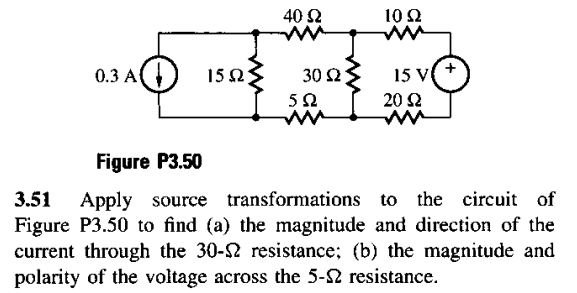

Primero transformamos la fuente de corriente:

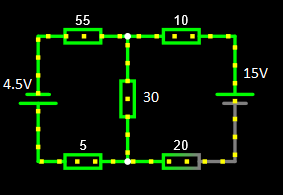

resolvemos por mallas

syms i1 i2 i3

vf1 = 15;
vf2 = 4.5;

r1 = 55;
r2 = 10;
r3 = 30;
r4= 5;
r5 = 20;

m_i1 = 90*i1-30*i2 == -vf2

$$m\_i1 = 90\,i_{1}-30\,i_{2}=-\frac{9}{2}$$

m_i2 = -30*i1+60*i2 == -vf1

$$m\_i2 = 60\,i_{2}-30\,i_{1}=-15$$

m = [90 -30;-30 60];
n = [-9/2;-15];
h = m\n % corrientes de cada malla 

h =         -0.16
        -0.33


ir3 = h(2,1)-h(1,1) %corriente en r3

ir3 =         -0.17


vemos que la corriente en r3 va hacia abajo, ahora calculamos la tension en r4:

vr4 = r4*h(1,1) %tension en r4

vr4 =          -0.8


Nos da una tension negativa por lo tanto va hacia la izquierda. Verficamos en el simulador